# ***Methylococcus capsulatus***** Monoculture S3 (30C, 37C, 42C, 47C) with 4Z Models**

**Loyal Murphy - February 8, 2024**

### Initialization

clear variables
clc

### Import and separate the data

scans = dir('*.csv');
% Preallocate the matrices
C30_data = {};
C37_data = {};
C42_data = {};
C47_data = {};
c30 = 0;
c37 = 0;
c42 = 0;
c47 = 0;

for i = 1:length(scans)
    clear n
    n = scans(i).name;
    if startsWith(n,'Cap4') || startsWith(n,'Cap5') || startsWith(n,'Cap6')
        c30 = c30 + 1;
        C30_data{c30,1} = readtable(n);
        C30_data{c30,2} = datetime(2023,02,str2double(n(15:16)),str2double(n(18:19)),str2double(n(21:22)),str2double(n(24:25)));
    elseif startsWith(n,'Cap1') || startsWith(n,'Cap2') || startsWith(n,'Cap3')
        c37 = c37 + 1;
        C37_data{c37,1} = readtable(n);
        C37_data{c37,2} = datetime(2023,02,str2double(n(15:16)),str2double(n(18:19)),str2double(n(21:22)),str2double(n(24:25)));
    elseif startsWith(n,'C42')
        c42 = c42 + 1;
        C42_data{c42,1} = readtable(n);
        C42_data{c42,2} = datetime(2023,02,str2double(n(15:16)),str2double(n(18:19)),str2double(n(21:22)),str2double(n(24:25)));
    elseif startsWith(n,'C47')
        c47 = c47 + 1;
        C47_data{c47,1} = readtable(n);
        C47_data{c47,2} = datetime(2023,02,str2double(n(15:16)),str2double(n(18:19)),str2double(n(21:22)),str2double(n(24:25)));
    end
end

to = datetime(2023,02,06,13,46,00); %Time CH4 was added (30 and 37)
to2 = datetime(2023,02,22,13,10,00); %Time CH4 was added (42 and 47)

### Get the averages and standard deviations of the data

pts30 = length(C30_data)/3; %Doesn't matter which dataset you choose
for j = 1:pts30 
    C30_ave(j) = mean([C30_data{j,1}.Abs(C30_data{j,1}.nm == 600),...
        C30_data{j+pts30,1}.Abs(C30_data{j+pts30,1}.nm == 600),...
        C30_data{j+2*pts30,1}.Abs(C30_data{j+2*pts30,1}.nm == 600)]);
    C30_std(j) = std([C30_data{j,1}.Abs(C30_data{j,1}.nm == 600),...
        C30_data{j+pts30,1}.Abs(C30_data{j+pts30,1}.nm == 600),...
        C30_data{j+2*pts30,1}.Abs(C30_data{j+2*pts30,1}.nm == 600)],1);
    C30_times(j) = hours(mean([C30_data{j,2},...
        C30_data{j+pts30,2},...
        C30_data{j+2*pts30,2}]) - to);
end

pts37 = length(C37_data)/3; %Doesn't matter which dataset you choose
for j = 1:pts37
    C37_ave(j) = mean([C37_data{j,1}.Abs(C37_data{j,1}.nm == 600),...
        C37_data{j+pts37,1}.Abs(C37_data{j+pts37,1}.nm == 600),...
        C37_data{j+2*pts37,1}.Abs(C37_data{j+2*pts37,1}.nm == 600)]);
    C37_std(j) = std([C37_data{j,1}.Abs(C37_data{j,1}.nm == 600),...
        C37_data{j+pts37,1}.Abs(C37_data{j+pts37,1}.nm == 600),...
        C37_data{j+2*pts37,1}.Abs(C37_data{j+2*pts37,1}.nm == 600)],1);
    C37_times(j) = hours(mean([C37_data{j,2},...
        C37_data{j+pts37,2},...
        C37_data{j+2*pts37,2}]) - to);
end

pts42 = length(C42_data)/3; %Doesn't matter which dataset you choose
for j = 1:pts42
    C42_ave(j) = mean([C42_data{j,1}.Abs(C42_data{j,1}.nm == 600),...
        C42_data{j+pts42,1}.Abs(C42_data{j+pts42,1}.nm == 600),...
        C42_data{j+2*pts42,1}.Abs(C42_data{j+2*pts42,1}.nm == 600)]);
    C42_std(j) = std([C42_data{j,1}.Abs(C42_data{j,1}.nm == 600),...
        C42_data{j+pts42,1}.Abs(C42_data{j+pts42,1}.nm == 600),...
        C42_data{j+2*pts42,1}.Abs(C42_data{j+2*pts42,1}.nm == 600)],1);
    C42_times(j) = hours(mean([C42_data{j,2},...
        C42_data{j+pts42,2},...
        C42_data{j+2*pts42,2}]) - to2);
end

pts47 = length(C47_data)/3; %Doesn't matter which dataset you choose
for j = 1:pts47
    C47_ave(j) = mean([C47_data{j,1}.Abs(C47_data{j,1}.nm == 600),...
        C47_data{j+pts47,1}.Abs(C47_data{j+pts47,1}.nm == 600),...
        C47_data{j+2*pts47,1}.Abs(C47_data{j+2*pts47,1}.nm == 600)]);
    C47_std(j) = std([C47_data{j,1}.Abs(C47_data{j,1}.nm == 600),...
        C47_data{j+pts47,1}.Abs(C47_data{j+pts47,1}.nm == 600),...
        C47_data{j+2*pts47,1}.Abs(C47_data{j+2*pts47,1}.nm == 600)],1);
    C47_times(j) = hours(mean([C47_data{j,2},...
        C47_data{j+pts47,2},...
        C47_data{j+2*pts47,2}]) - to2);
end

% Dilution numbers and gDCW conversion
C30_factor = 1;
C37_factor = [1 1 1 1 1 5 5 8 10 20 20 20 20 20];
C42_factor = [1 1 3 3 5 8 10 10 20 20 20 20 20];
C47_factor = [1 1 3 3 5 8 10 10 20 20 20 20];

C30_ave = C30_ave.*C30_factor*0.235;
C30_std = C30_std.*C30_factor*0.235;

C37_ave = C37_ave.*C37_factor*0.235;
C37_std = C37_std.*C37_factor*0.235;

C42_ave = C42_ave.*C42_factor*0.235;
C42_std = C42_std.*C42_factor*0.235;

C47_ave = C47_ave.*C47_factor*0.235;
C47_std = C47_std.*C47_factor*0.235;

### Plot the Data

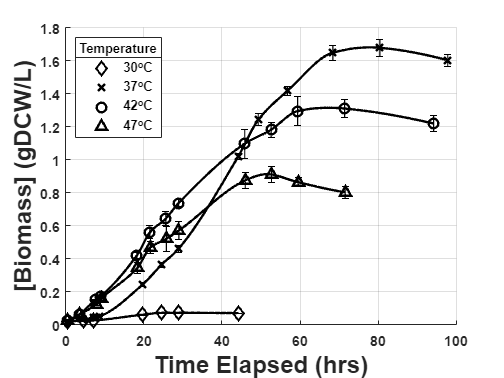

figure()
set(gca,'FontSize',12,'FontWeight','bold');
hold on
xq1 = linspace(C30_times(1),C30_times(end),200);
yq1 = makima(C30_times,C30_ave,xq1);
plot(C30_times,C30_ave,'kd',xq1,yq1,'k','LineWidth',2,'MarkerSize',8);
errorbar(C30_times,C30_ave,C30_std,'k','LineStyle','none','LineWidth',1,'MarkerSize',10);

xq2 = linspace(C37_times(1),C37_times(end),200);
yq2 = makima(C37_times,C37_ave,xq2);
plot(C37_times,C37_ave,'kx',xq2,yq2,'k','LineWidth',2,'MarkerSize',8);
errorbar(C37_times,C37_ave,C37_std,'k','LineStyle','none','LineWidth',1);

xq3 = linspace(C42_times(1),C42_times(end),200);
yq3 = makima(C42_times,C42_ave,xq3);
plot(C42_times,C42_ave,'ko',xq3,yq3,'k','LineWidth',2,'MarkerSize',8);
errorbar(C42_times,C42_ave,C42_std,'k','LineStyle','none','LineWidth',1);

xq4 = linspace(C47_times(1),C47_times(end),200);
yq4 = makima(C47_times,C47_ave,xq4);
plot(C47_times,C47_ave,'k^',xq4,yq4,'k','LineWidth',2,'MarkerSize',8);
errorbar(C47_times,C47_ave,C47_std,'k','LineStyle','none','LineWidth',1);
hold off

grid on
xlabel('Time Elapsed (hrs)','FontSize',20,'FontWeight','bold')
ylabel('[Biomass] (gDCW/L)','FontSize',20,'FontWeight','bold')
lgd = legend('30^{o}C','','','37^{o}C','','','42^{o}C','','','47^{o}C','','','location','northwest');
title(lgd,'Temperature')
xlim([0 100])

### Plot the Data with 4Z model and Display Values

% Make data matrices %
for k = 1:length(C30_data)
    C30_gDCW(k) = C30_data{k,1}.Abs(C30_data{k,1}.nm == 600);
end
C30_gDCW = reshape(C30_gDCW,length(C30_gDCW)/3,3) * 0.235 .* C30_factor';

for k = 1:length(C37_data)
    C37_gDCW(k) = C37_data{k,1}.Abs(C37_data{k,1}.nm == 600);
end
C37_gDCW = reshape(C37_gDCW,length(C37_gDCW)/3,3) * 0.235 .* C37_factor';

for k = 1:length(C42_data)
    C42_gDCW(k) = C42_data{k,1}.Abs(C42_data{k,1}.nm == 600);
end
C42_gDCW = reshape(C42_gDCW,length(C42_gDCW)/3,3) * 0.235 .* C42_factor';

for k = 1:length(C47_data)
    C47_gDCW(k) = C47_data{k,1}.Abs(C47_data{k,1}.nm == 600);
end
C47_gDCW = reshape(C47_gDCW,length(C47_gDCW)/3,3) * 0.235 .* C47_factor';

% Predefine variables and initial guesses for solver %
tempNames = ["30^{o}C","37^{o}C","42^{o}C","47^{o}C"];
color = [0.6 0 0];
Inits = {[0.1,0.01,0],[1.7,0.15,20],[1.3,0.15,5],[0.9,0.1,5]};
Inits2 = {[0.01,1],[0.15,5],[0.15,2],[0.1,2]};
Times = {C30_times';C37_times';C42_times';C47_times'};
all_gDCWs = {C30_gDCW;C37_gDCW;C42_gDCW;C47_gDCW};

% Storage for later variables %   
K_vals = zeros(3,4);
tLAG_vals = zeros(3,4);
mu_max_vals4 = zeros(3,4);
td_vals4 = zeros(3,4);
for i = 1:length(Times)
    % Plot the individual data sets with their Gompertz models
    x = Times{i}(1:end-1);
    gDCW = all_gDCWs{i,1}(1:end-1,:);
    for j = 1:3
        y = gDCW(:,j);
        Xo = y(1); %Initial biomass
        foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0],'Upper',[3,0.35,30,Xo*2],'StartPoint',[Inits{i},Xo]);
        ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering
        % a = Carrying Capacity
        % b = Growth Rate
        % c = Lag Time
        % d = Vertical Shift

        % Gompertz Model Predictions %
        [curve_ZMB,sZMB] = fit(x,y,ft_ZMB);
        K_vals(j,i) = curve_ZMB.a;
        tLAG_vals(j,i) = curve_ZMB.c;
        D_vals(j,i) = curve_ZMB.d;

        % Lastly, try using the piecewise model from 0 to Tlag
        tEXP5 = linspace(0,tLAG_vals(j,i),50);
        fo5 = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0],'Upper',[0.2,0.3,15],'StartPoint',[Xo,Inits2{i}]);
        ft_XMXo5 = fittype('expo(t,x1,x2,x3)','independent',{'t'},'options',fo5);
        [curve_XMXo5,sXMXo5] = fit(tEXP5',curve_ZMB(tEXP5),ft_XMXo5);
        mu_max_vals5(j,i) = curve_XMXo5.x2;
        td_vals5(j,i) = curve_XMXo5.x3;
    end
end

#### Plot the results of the modeling

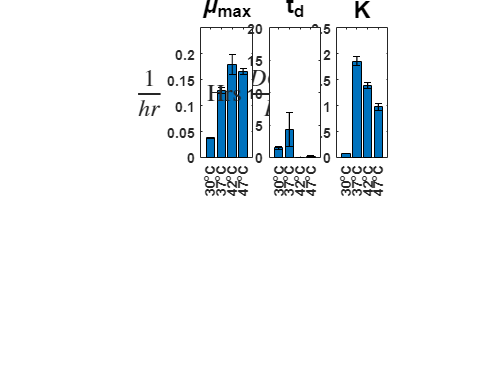

pub_idx = [1,2,3,4];

figure(); clf;
subplot(2,6,5)
statDCW_vals = mean(K_vals) + mean(D_vals);
statDCW_std = std(K_vals);
hold on
bar(tempNames,statDCW_vals(pub_idx));
errorbar(statDCW_vals(pub_idx),statDCW_std(pub_idx),'LineStyle','none','Color','k','LineWidth',1);
hold off
set(gca,'FontSize',12,'FontWeight','bold');
ylabel('$\frac{gDCW}{L}$','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,2.5]);
title('K','FontSize',20,'FontWeight','bold');
box on;

ae = gca;
save('fe','ae');

%figure(); clf;
subplot(2,6,3)
mu_max_ave = mean(mu_max_vals5);
mu_max_std = std(mu_max_vals5);
hold on
bar(tempNames,mu_max_ave(pub_idx));
errorbar(mu_max_ave(pub_idx),mu_max_std(pub_idx),'LineStyle','none','Color','k','LineWidth',1);
hold off
set(gca,'FontSize',12,'FontWeight','bold');
title('\mu_{max}','FontSize',20,'FontWeight','bold')
ylabel('$\frac{1}{hr}$','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,0.25]);
box on;

ac = gca;
save('fc','ac');

% Tlag - td shows time actively growing on AD %
subplot(2,6,4)
%activeT = tLAG_vals - td_vals;
td_ave = mean(td_vals5);
td_std = std(td_vals5);
hold on
b = bar(tempNames,td_ave(pub_idx));
errorbar(td_ave(pub_idx),td_std(pub_idx),'LineStyle','none','Color','k','LineWidth',1);
hold off
set(gca,'FontSize',12,'FontWeight','bold');
%title('Active Time (T_{lag} - t_{d})','FontSize',20,'FontWeight','bold')
title('t_d','FontSize',20,'FontWeight','bold')
ylabel('Hrs','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,20]);
box on;


ad = gca;
save('fd','ad');

#### Plot Gompertz data and models

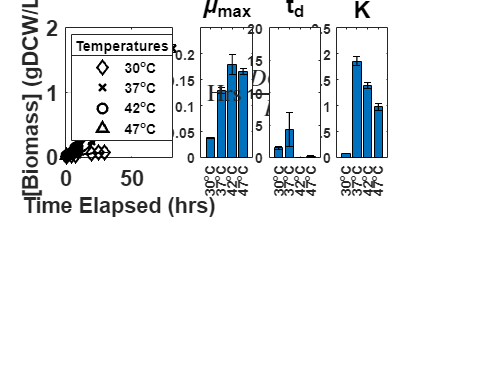

Marker = ["d","x","o","^"];
all_Times = {C30_times';C37_times';C42_times';C47_times'};
all_gDCWs = {C30_gDCW;C37_gDCW;C42_gDCW;C47_gDCW};

%figure(); clf; %Start a new plot
subplot(2,3,1);
%All the code below is to plot the Gompertz fits onto monoculture data
for i = pub_idx
    gDCWs = all_gDCWs{i};
    Times = all_Times{i}; 
    xAve = mean(gDCWs,2);
    xstd = std(gDCWs,[],2);

    Xo = gDCWs(1); %Initial biomass
    foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0],'Upper',[3,0.35,100,Xo*2],'StartPoint',[Inits{i},Xo]);
    ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zwietering

    [curve_ZMB,sZMB] = fit(Times(1:end-1),xAve(1:end-1),ft_ZMB);
    tSpace = linspace(0,max(Times(1:end-1)),301);

    %Plot the Data, Error Bars, and Model in order.
    hold on
    plot(Times(1:end-1),xAve(1:end-1),Marker(i),'Color','k','MarkerSize',8,'LineStyle','none','LineWidth',2);
    errorbar(Times(1:end-1),xAve(1:end-1),xstd(1:end-1),'k','LineStyle','none','LineWidth',1);
    plot(tSpace,curve_ZMB(tSpace),'k-','LineWidth',2);
    hold off
end
ax = gca;
ax.FontSize = 18;
ax.FontWeight = 'bold';
xlabel('Time Elapsed (hrs)','FontSize',18,'FontWeight','bold');
ylabel('[Biomass] (gDCW/L)','FontSize',18,'FontWeight','bold');
lgd = legend('30^{o}C','','','37^{o}C','','','42^{o}C','','','47^{o}C','','','FontSize',12,'location','northwest');
title(lgd,'Temperatures')
axis([0 81 0 2]);
ax.YGrid = 'on';
box(ax,'on');


aab = gca;
save('fab','aab');